% divide 5*10 grids for data from simulation
addpath(genpath(pwd));
load('standard_data.mat')
freqsimu=ones(5,10,35);
i=1;
while i<1001
    if mu_trans(i)==0.5
        indexmu=5;
    else
        indexmu=ceil((mu_trans(i)-0.25)/0.05+0.0000001);
    end
    if rejection_of_factions(i)==0.5
        indexre=10;
    else
        indexre=ceil(rejection_of_factions(i)/0.05+0.0000001);
    end
    freqsimu(indexmu,indexre,sum(freqsimu(indexmu,indexre,:)~=1)+1)=op_trans(i);
    i=i+1;
end

% generate data through the probability distribution
loc=zeros(1000,3);
iloc=1;
while iloc<=1000
    mu=1;
    while mu>0.5
        mu=0.25+0.255*rand();
    end
    op=0.5*rand();
    re=0.5*rand();
    A1=(0.5-re)/(1+exp(100*(re-(1*mu-0.1))));
    A2=re/(1+exp(100*(-re+(1.8*mu-0.45))));
    m1=-(0.0004*exp(12*mu))+0.1614;
    m2=(0.09*exp(2*mu))*(0.65*re+1);
    sigma1=0.08*mu-0.005;
    sigma2=0.16*mu-0.035;
    prob=(A1*normcdf(op+0.005,m1,sigma1)+A2*normcdf(op+0.005,m2,sigma2))/(A1+A2)-(A1*normcdf(op,m1,sigma1)+A2*normcdf(op,m2,sigma2))/(A1+A2);
    if rand<prob
        loc(iloc,:)=[mu,re,op];
        iloc=iloc+1;
    end
end

% draw diagrams for generated data
scatter3(loc(:,1),loc(:,2),loc(:,3))
scatter(loc(:,2),loc(:,1))

% divide grids to 5*10 for data generated by our formula
n=length(loc);
freqpro=ones(5,10,ceil(n/50)*3);
i=1;
while i<n+1
    if abs(loc(i,1)-0.5)<0.0000001
        indexmu=5;
    else
        indexmu=ceil((loc(i,1)-0.25)/0.05+0.0000001);
    end
    if abs(0.5-loc(i,2))<0.0000001
        indexre=10;
    else
        indexre=ceil(loc(i,2)/0.05+0.0000001);
    end
    freqpro(indexmu,indexre,sum(freqpro(indexmu,indexre,:)~=1)+1)=loc(i,3);
    i=i+1;
end

% ks test
len_op=size(freqpro,3);
matrix_h=zeros(5,10);
matrix_p=zeros(5,10);
for indexmu=1:5
    for indexre=1:10
        simudata=reshape(freqsimu(indexmu,indexre,:),[35 1]);
        simudata=simudata(simudata~=1);
        prodata=reshape(freqpro(indexmu,indexre,:),[len_op 1]);
        prodata=prodata(prodata~=1);
        [h,p]=kstest2(simudata,prodata);
        matrix_h(indexmu,indexre)=h;
        matrix_p(indexmu,indexre)=p;
    end
end
1-sum(sum(matrix_h))/50

% run 20 times to test on average
datagenerated=ones(1000,3,20);
passornot=ones(5,10,20);
pvalue=ones(5,10,20);
percentage=ones(20,1);
for run=1:20
    % generate data through the probability distribution
    loc=zeros(1000,3);
    iloc=1;
    while iloc<=1000
        mu=1;
        while mu>0.5
            mu=0.25+0.255*rand();
        end
        op=0.5*rand();
        re=0.5*rand();
        A1=(0.5-re)/(1+exp(100*(re-(1*mu-0.1))));
        A2=re/(1+exp(100*(-re+(1.8*mu-0.45))));
        m1=-(0.0004*exp(12*mu))+0.1614;
        m2=(0.09*exp(2*mu))*(0.65*re+1);
        sigma1=0.08*mu-0.005;
        sigma2=0.16*mu-0.035;
        prob=(A1*normcdf(op+0.005,m1,sigma1)+A2*normcdf(op+0.005,m2,sigma2))/(A1+A2)-(A1*normcdf(op,m1,sigma1)+A2*normcdf(op,m2,sigma2))/(A1+A2);
        if rand<prob
            loc(iloc,:)=[mu,re,op];
            iloc=iloc+1;
        end
    end
    % divide grids to 5*10 for data generated by our formula
    n=length(loc);
    freqpro=ones(5,10,ceil(n/50)*3);
    i=1;
    while i<n+1
        if abs(loc(i,1)-0.5)<0.0000001
            indexmu=5;
        else
            indexmu=ceil((loc(i,1)-0.25)/0.05+0.0000001);
        end
        if abs(0.5-loc(i,2))<0.0000001
            indexre=10;
        else
            indexre=ceil(loc(i,2)/0.05+0.0000001);
        end
        freqpro(indexmu,indexre,sum(freqpro(indexmu,indexre,:)~=1)+1)=loc(i,3);
        i=i+1;
    end
    % ks test
    len_op=size(freqpro,3);
    matrix_h=zeros(5,10);
    matrix_p=zeros(5,10);
    for indexmu=1:5
        for indexre=1:10
            simudata=reshape(freqsimu(indexmu,indexre,:),[35 1]);
            simudata=simudata(simudata~=1);
            prodata=reshape(freqpro(indexmu,indexre,:),[len_op 1]);
            prodata=prodata(prodata~=1);
            [h,p]=kstest2(simudata,prodata);
            matrix_h(indexmu,indexre)=h;
            matrix_p(indexmu,indexre)=p;
        end
    end
    % record
    datagenerated(:,:,run)=loc;
    passornot(:,:,run)=matrix_h;
    pvalue(:,:,run)=matrix_p;
    % what percentage of grids have passed the k-s test
    percentage(run)=1-sum(sum(matrix_h))/50;
end

% average percentage of passed grids in 20times k-s tests
mean(percentage)

ans = 0.8300

[a,b]=max(percentage);
a

a = 0.9200

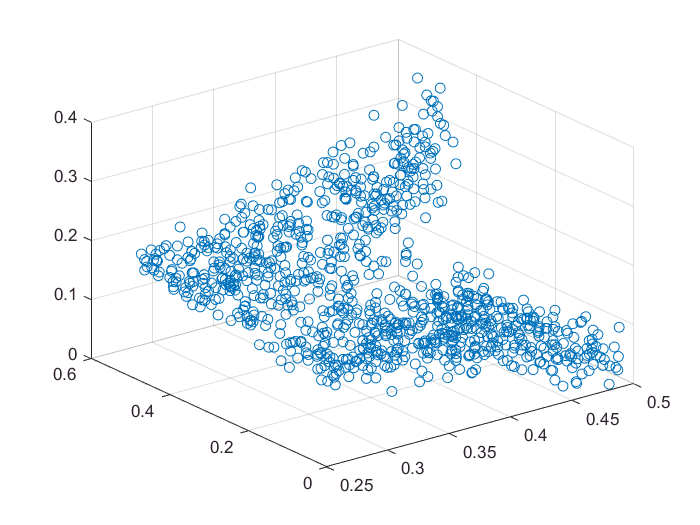

loc=datagenerated(:,:,b);
scatter3(loc(:,1),loc(:,2),loc(:,3))

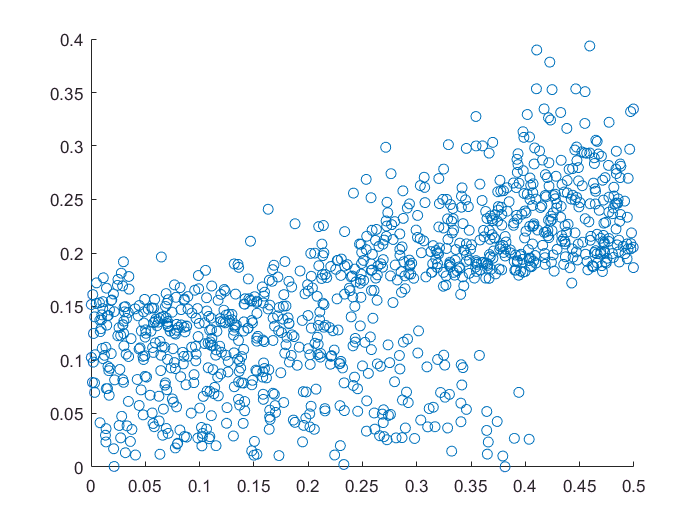

scatter(loc(:,2),loc(:,3))